# 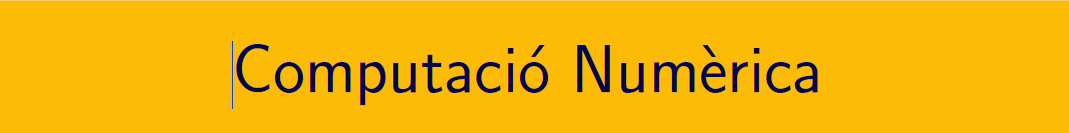

================================================================================

# Pràctica 12. Equacions diferencials ordinàries (II).

`Document preparat per M. Àngela Grau Gotés - 19 de maig de 2022`

## Estabilitat numèrica del mètode d'Euler

#### Problema de valors inicials

#### 
$$y'=-3 y\,, \quad y(0)=3\,, \quad y(25)=?$$


#### Solució analítica

syms y(t)
eqn = diff(y,t) == -3*y;
cond = y(0) == 3;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 3\,{\mathrm{e}}^{-3\,t}$$

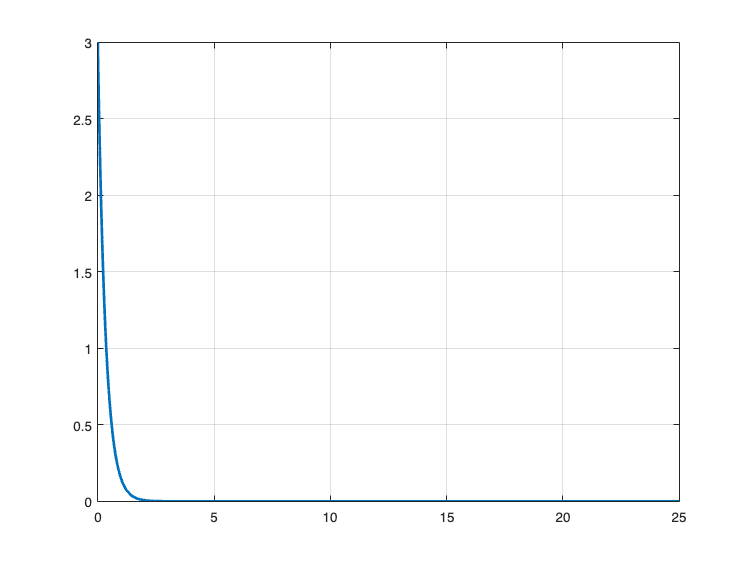

fplot(ySol,[0,25],'LineWidth',2),grid


a = 0; alpha = 3;     % y(a) = alpha
b = 25;               % y(b) = ...
u = linspace(a,b); yu = double(ySol(u));
f = @(t,y)(-3*y);

## Método de Euler: |`ah`| <1, a=-3, 

- h=0.2 (estabilitat numèrica) 

f = @(t,y)(-3*y);
h = 0.2; x = a:h:b; 
[Y1] = Euler(f,a,b,h,alpha);
errorGlobal = abs(Y1(end)-double(ySol(b)))

errorGlobal =    8.0359e-33

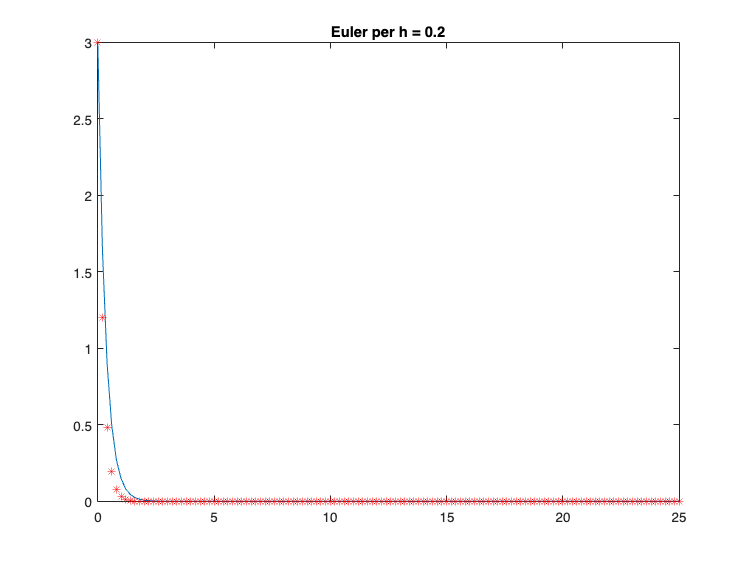


% Solució estable
plot(x,ySol(x),x,Y1,'*r'), title(['Euler per h = ', num2str(h)])
hold off

-  h=0.5 

f = @(t,y)(-3*y);
h = 0.5; x = a:h:b; 
[Y1] = Euler(f,a,b,h,alpha);
errorGlobal = abs(Y1(end)-double(ySol(b)))

errorGlobal =    2.6645e-15

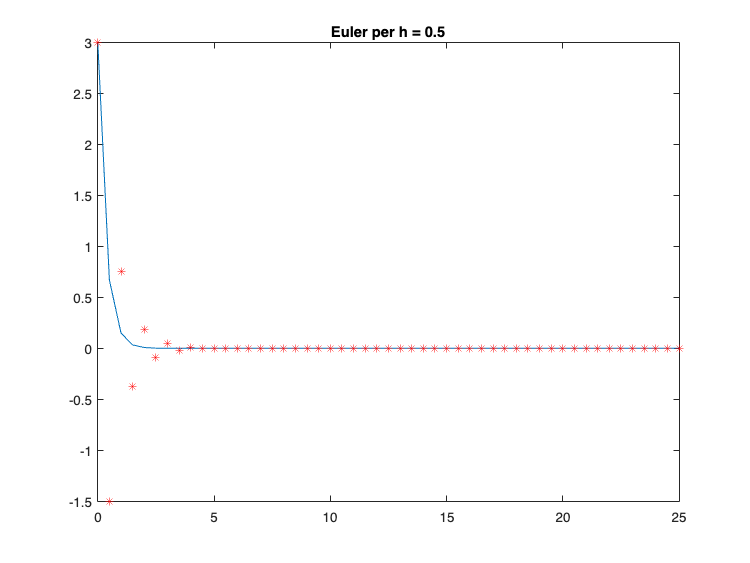


% Solució que comença a tenir inestabilitat
plot(x,ySol(x),x,Y1,'*r'), title(['Euler per h = ', num2str(h)])

-   h=2/3 (oscila)

h = 2/3;x = a:h:b; 
[Y1] = Euler(f,a,b,h,alpha);
errorGlobal = abs(Y1(end)-double(ySol(b)))

errorGlobal =      3

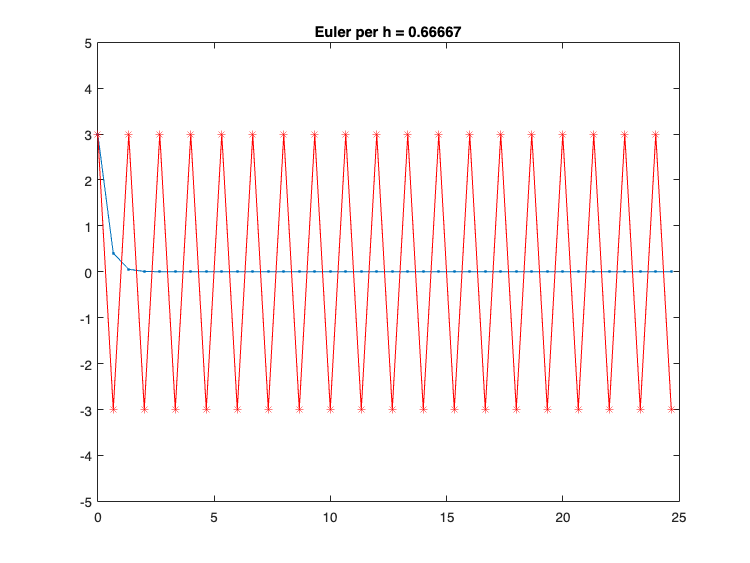


% Solució que oscila
plot(x,ySol(x),'.-',x,Y1,'*-r'), title(['Euler per h = ', num2str(h)])
ylim([-5 5])

-  h=0.69 (inestable numericament)


h = 0.69; x = a:h:b; 
[Y1] = Euler(f,a,b,h,alpha);
errorGlobal = abs(Y1(end)-double(ySol(b)))

errorGlobal =        34.272

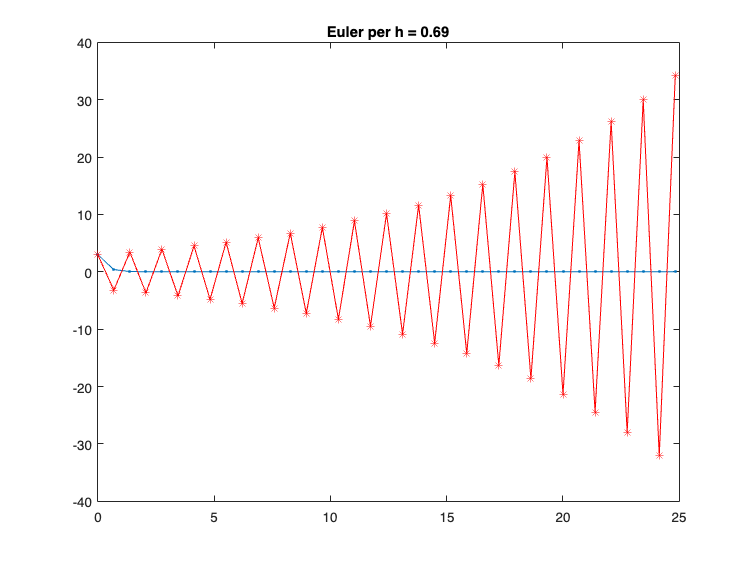

plot(x,ySol(x),'.-',x,Y1,'*-r'), title(['Euler per h = ', num2str(h)])

-  h= .... > 2/3

h = 0.75;
x = a:h:b; 
[Y1] = Euler(f,a,b,h,alpha);
errorGlobal = abs(Y1(end)-double(ySol(b)))

errorGlobal =        4733.2

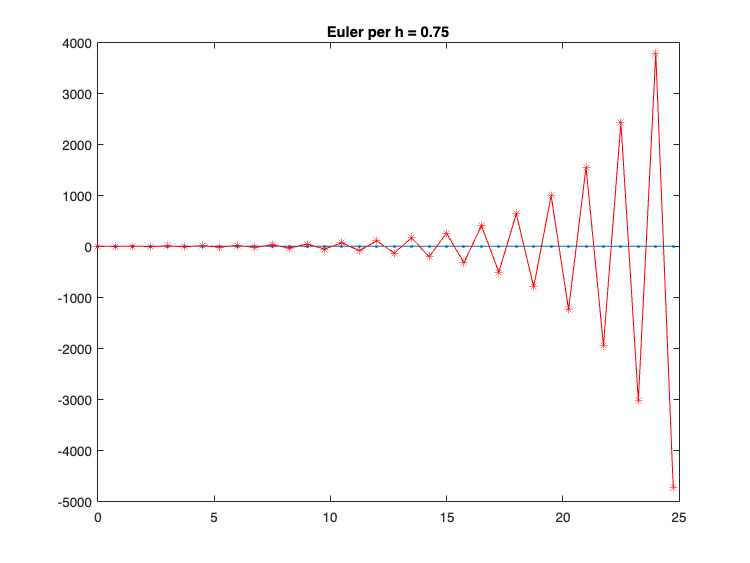


plot(x,ySol(x),'.-',x,Y1,'*-r'), title(['Euler per h = ', num2str(h)])

## PRACTIQUEM... 

### Exercici. 

 Resoleu els exercicis del document practica12_edos_II.pdf disponible en el campus virtual.

## Vegeu: prac12_19maig_estabilitatEuler_practiquem.html

function [ w ] = Euler(f,a,b,h,alpha)    % Ordre 0(h)
    % Mètode d'Euler
    t = [a:h:b];
    N = length(t);
    w(1) = alpha;
    for i = 1:N-1
        w(i+1) = w(i)+h*f(t(i),w(i));
    end
end

`Dijous 19 de maig 2022, preparat per M. Àngela Grau Gotés`